Brief summary of this function.

Detailed explanation of this function.

clc
clear
Q = zeros(9);


Q(2,2) = .1;
Q(3,3) = .1;
Q(5,5) = .1;
Q(4,4) = .1;
Q(6,6) = .1;

%Q(7,7) = .1;
%Q(8,8) = .1;
%Q(9,9) = .1;
Q =   100.*Q; 

R = eye(5);
R(4,4) = 100;
R(5,5) = 100;

A = load('A.mat').A;
B   = load('B.mat').B;
A = double(A);
B = double(B);

Observe_widtf = 3;
H =eye(Observe_widtf,9);




C = H;
D = zeros(Observe_widtf,5);

[K,S,P] = lqr(A,B,Q,R)

K =    -0.0000   -0.0340    0.0000   -2.0983    0.0000   -0.6117   -0.3749   -0.0000   -0.0000
    0.0285    0.0000   -3.0879   -0.0000   -7.9921   -0.0000    0.0000    0.0445    0.0000
   -0.0000    3.0829    0.0000    1.0941   -0.0000  -22.0392    2.7664   -0.0000   -0.0000
    0.0001   -0.0265    0.0013   -0.0003    0.0078    0.3327   -0.0384    0.0010    0.0000
    0.0001    0.0265    0.0013    0.0003    0.0078   -0.3327    0.0384    0.0010   -0.0000


S =     0.0016   -0.0000   -0.0014    0.0000   -0.0073   -0.0000   -0.0000    0.0042   -0.0000
   -0.0000    0.9047   -0.0000    0.1115   -0.0000   -3.3965    0.4130   -0.0000    0.0000
   -0.0014   -0.0000    0.3288   -0.0000    0.3746    0.0000   -0.0000   -0.0706   -0.0000
    0.0000    0.1115   -0.0000    2.4950    0.0000   -0.1666    0.5487    0.0000    0.0000
   -0.0073   -0.0000    0.3746    0.0000    2.1826    0.0000    0.0000    0.1630   -0.0000
   -0.0000   -3.3965    0.0000   -0.1666    0.0000   42.6413   -4.9456    0.0000    0.0000
   -0.0000    0.4130   -0.0000    0.5487    0.0000   -4.9456    2.1076    0.0000    0.0000
    0.0042   -0.0000   -0.0706    0.0000    0.1630    0.0000    0.0000    5.4451    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


P =   -0.0000 + 0.0000i
  -0.0190 + 0.1650i
  -0.0190 - 0.1650i
  -0.1170 + 0.0000i
  -2.9208 + 0.0000i
  -7.8238 + 6.2816i
  -7.8238 - 6.2816i
 -21.0505 +14.1967i
 -21.0505 -14.1967i


save('K.mat','K')

%eig(round(A-B*K,5))
 sys2 = ss(A-B*K,B,C,D)

sys2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1     -0.0423  -3.889e-15       1.025    1.16e-16      -1.367   7.445e-15   6.175e-17      -9.826  -1.667e-17
   x2   3.852e-15      -6.468  -5.551e-15       1.565   3.819e-15      -34.97        4.14   3.703e-14   4.939e-13
   x3    -0.07312   4.768e-14      -20.71  -1.725e-15       25.53  -2.164e-13    1.39e-14     -0.3032   3.842e-16
   x4   5.888e-16      -1.051   1.132e-15      -3.389    2.05e-15       7.142      -1.208   5.588e-15  -6.993e-11
   x5     0.06047   1.865e-14      -7.894  -6.759e-16      -21.39  -8.506e-14   5.485e-15      0.1126   1.509e-16
   x6  -6.887e-16       1.135   1.044e-15      0.4015  -7.297e-16      -8.828       1.029  -6.687e-15   -2.87e-12
   x7           0           0           0           1           0        0.06           0           0           0
   x8           0           0           0           0           1       

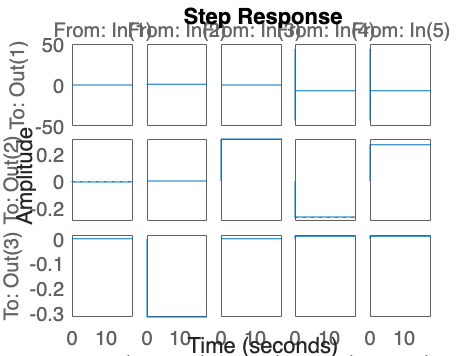

 step(sys2)

 %sys2 = ss(A,B,C,D);
 %step(sys2)